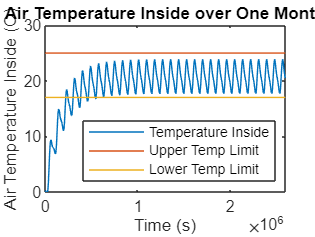

clear all
clf
month = 60*60*24*30;
start_temp = -3;
R_0 = 8.6903 * (10^-4);
R_rest = 0.0055 - R_0;

[t, T] = ode45(@solarODE, [0 month], start_temp);
T_air = (T - start_temp) * (R_rest/(R_rest + R_0));
plot (t, T_air)
hold on

temp_high = ones(length(t), 1) * 25;
temp_low = ones(length(t), 1) * 17;
plot(t, temp_high);
plot(t, temp_low);

xlabel("Time (s)");
ylabel("Air Temperature Inside (C)")
title("Air Temperature Inside over One Month")
legend("Temperature Inside", "Upper Temp Limit", "Lower Temp Limit", "Location","Southeast");
axis([0 t(end) 0 30])